init_method = 'spec'

init_method = 'spec'

x= x_noisy;
verbose = true;
% Sigma = known covariance matrix
%data generation
% created 01/26/2024
init_method

init_method = 'spec'

% spectral initialization
n = size(x,2);
p = size(x,1);
if strcmp(init_method, 'spec')
    H_hat = (x' * x)/n;
    [V,D] = eig(H_hat);
    [d,ind] = sort(diag(D), "descend");
    Ds = D(ind,ind);
    Vs = V(:,ind);
    [cluster_est_now,C] = kmeans(Vs(:,1),K);
elseif strcmp(init_method, "hc")
    Z = linkage(x', 'ward');
    cluster_est_now = cluster(Z, 'Maxclust',K);
end
cluster_est_now = cluster_est_now .* (cluster_est_now ~= 2) + (cluster_est_now == 2)* (-1);
cluster_est_now = cluster_est_now';

thres = sqrt(2 * log(p) );
Sigma_diagonal = diag(Sigma);
X_tilde =     inv(Sigma) *  x;
X_tilde_now =     X_tilde;

cluster_acc_before_thres = max( mean(cluster_true ==  cluster_est_now), mean(cluster_true == -cluster_est_now));



n_g1_now = sum(cluster_est_now == 1);
n_g2_now = sum(cluster_est_now ==-1);

if verbose
    100
    fprintf("\np = %i, acc_init: %f \n", p, cluster_acc_before_thres);
    fprintf("n_{G1}_init = %i, n_{G1}_init = %i\n", n_g1_now, n_g2_now )
    fprintf("threshold: (%f)\n", thres)
end

ans = 100


p = 5000, acc_init: 0.960000 


n_{G1}_init = 98, n_{G1}_init = 102


threshold: (4.127273)


cluster_acc_now = cluster_acc_before_thres;
for iter = 1:n_iter
    fprintf("\n%i th thresholding\n\n", iter)
    % 1. estimate cluster means


    if max(n_g1_now, n_g2_now) ==n
        %fprintf("all observations are clustered into one group")
        cluster_acc = 0.5;
        return 
    end
    
    
            
    X_tilde_now_g1 = X_tilde(:, (cluster_est_now ==  1)); 
    X_tilde_now_g2 = X_tilde(:, (cluster_est_now == -1));
        
    X_tilde_bar_g1 = mean(X_tilde_now_g1, 2);  
    X_tilde_bar_g2 = mean(X_tilde_now_g2, 2);
            
    % 2. threshold the data matrix
    abs_diff = abs(X_tilde_bar_g1 - X_tilde_bar_g2)./diag(Sigma) * sqrt( n_g1_now*n_g2_now/n );
    abs_diff_sort = -sort(-abs_diff);
    top_10 = abs_diff_sort(1:10);

    
    s_hat = abs_diff > thres;
    n_entries_survived = sum(s_hat);

    if n_entries_survived == 0
        cluster_acc = 0.5;
        break
    end
    
    Sigma_s_hat_now = Sigma(s_hat,s_hat);
    X_tilde_now  = X_tilde(s_hat,:);
    
    find(s_hat)
    
    A_now = X_tilde_now' * Sigma_s_hat_now * X_tilde_now;
 
    Z_now = kmeans_sdp( A_now/ n, K);     
    cluster_est_now = estimate_cluster(Z_now, rounding, n, cluster_true);
        
    cluster_acc_now = max( ...
                    mean(cluster_true == cluster_est_now), ...
                    mean(cluster_true == -cluster_est_now) ...
                    );
    n_g1_now = sum(cluster_est_now == 1);
    n_g2_now = sum(cluster_est_now ==-1);
    if verbose
        fprintf("%i entries survived \n\n",n_entries_survived)
        fprintf("normalized difference top 10 max: (%f) * sigma \n", top_10)
        fprintf("n_{G1}_now = %i, n_{G1}_now = %i\n", n_g1_now, n_g2_now )
        fprintf("acc_now= %f", cluster_acc_now);
    end
    % end one iteration
end % end of iterative algorithm

1 th thresholding



ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


  breakyes=1.0,  maxresidual < 1.00e-06

21 entries survived 



normalized difference top 10 max: (8.504201) * sigma 
normalized difference top 10 max: (8.461422) * sigma 
normalized difference top 10 max: (7.228606) * sigma 
normalized difference top 10 max: (6.892151) * sigma 
normalized difference top 10 max: (6.856450) * sigma 
normalized difference top 10 max: (6.455206) * sigma 
normalized difference top 10 max: (6.432507) * sigma 
normalized difference top 10 max: (6.206720) * sigma 
normalized difference top 10 max: (5.845313) * sigma 
normalized difference top 10 max: (5.579769) * sigma 


n_{G1}_now = 104, n_{G1}_now = 96


acc_now= 0.970000

2 th thresholding



ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


  breakyes=1.0,  maxresidual < 1.00e-06

23 entries survived 



normalized difference top 10 max: (8.801046) * sigma 
normalized difference top 10 max: (8.008842) * sigma 
normalized difference top 10 max: (7.401026) * sigma 
normalized difference top 10 max: (7.100254) * sigma 
normalized difference top 10 max: (7.059310) * sigma 
normalized difference top 10 max: (6.836274) * sigma 
normalized difference top 10 max: (6.518251) * sigma 
normalized difference top 10 max: (6.197968) * sigma 
normalized difference top 10 max: (6.121985) * sigma 
normalized difference top 10 max: (5.764301) * sigma 


n_{G1}_now = 104, n_{G1}_now = 96


acc_now= 0.980000

3 th thresholding



ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


25 entries survived 



normalized difference top 10 max: (8.166586) * sigma 
normalized difference top 10 max: (7.985929) * sigma 
normalized difference top 10 max: (7.529426) * sigma 
normalized difference top 10 max: (7.470514) * sigma 
normalized difference top 10 max: (7.348752) * sigma 
normalized difference top 10 max: (6.946871) * sigma 
normalized difference top 10 max: (6.496807) * sigma 
normalized difference top 10 max: (6.405356) * sigma 
normalized difference top 10 max: (6.030260) * sigma 
normalized difference top 10 max: (5.694436) * sigma 


n_{G1}_now = 104, n_{G1}_now = 96


acc_now= 0.980000

4 th thresholding



ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


25 entries survived 



normalized difference top 10 max: (8.166586) * sigma 
normalized difference top 10 max: (7.985929) * sigma 
normalized difference top 10 max: (7.529426) * sigma 
normalized difference top 10 max: (7.470514) * sigma 
normalized difference top 10 max: (7.348752) * sigma 
normalized difference top 10 max: (6.946871) * sigma 
normalized difference top 10 max: (6.496807) * sigma 
normalized difference top 10 max: (6.405356) * sigma 
normalized difference top 10 max: (6.030260) * sigma 
normalized difference top 10 max: (5.694436) * sigma 


n_{G1}_now = 104, n_{G1}_now = 96


acc_now= 0.980000

5 th thresholding



ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


25 entries survived 



normalized difference top 10 max: (8.166586) * sigma 
normalized difference top 10 max: (7.985929) * sigma 
normalized difference top 10 max: (7.529426) * sigma 
normalized difference top 10 max: (7.470514) * sigma 
normalized difference top 10 max: (7.348752) * sigma 
normalized difference top 10 max: (6.946871) * sigma 
normalized difference top 10 max: (6.496807) * sigma 
normalized difference top 10 max: (6.405356) * sigma 
normalized difference top 10 max: (6.030260) * sigma 
normalized difference top 10 max: (5.694436) * sigma 


n_{G1}_now = 104, n_{G1}_now = 96


acc_now= 0.980000

6 th thresholding



ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


25 entries survived 



normalized difference top 10 max: (8.166586) * sigma 
normalized difference top 10 max: (7.985929) * sigma 
normalized difference top 10 max: (7.529426) * sigma 
normalized difference top 10 max: (7.470514) * sigma 
normalized difference top 10 max: (7.348752) * sigma 
normalized difference top 10 max: (6.946871) * sigma 
normalized difference top 10 max: (6.496807) * sigma 
normalized difference top 10 max: (6.405356) * sigma 
normalized difference top 10 max: (6.030260) * sigma 
normalized difference top 10 max: (5.694436) * sigma 


n_{G1}_now = 104, n_{G1}_now = 96


acc_now= 0.980000

7 th thresholding



ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


25 entries survived 



normalized difference top 10 max: (8.166586) * sigma 
normalized difference top 10 max: (7.985929) * sigma 
normalized difference top 10 max: (7.529426) * sigma 
normalized difference top 10 max: (7.470514) * sigma 
normalized difference top 10 max: (7.348752) * sigma 
normalized difference top 10 max: (6.946871) * sigma 
normalized difference top 10 max: (6.496807) * sigma 
normalized difference top 10 max: (6.405356) * sigma 
normalized difference top 10 max: (6.030260) * sigma 
normalized difference top 10 max: (5.694436) * sigma 


n_{G1}_now = 104, n_{G1}_now = 96


acc_now= 0.980000

8 th thresholding



ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


25 entries survived 



normalized difference top 10 max: (8.166586) * sigma 
normalized difference top 10 max: (7.985929) * sigma 
normalized difference top 10 max: (7.529426) * sigma 
normalized difference top 10 max: (7.470514) * sigma 
normalized difference top 10 max: (7.348752) * sigma 
normalized difference top 10 max: (6.946871) * sigma 
normalized difference top 10 max: (6.496807) * sigma 
normalized difference top 10 max: (6.405356) * sigma 
normalized difference top 10 max: (6.030260) * sigma 
normalized difference top 10 max: (5.694436) * sigma 


n_{G1}_now = 104, n_{G1}_now = 96


acc_now= 0.980000

9 th thresholding



ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


25 entries survived 



normalized difference top 10 max: (8.166586) * sigma 
normalized difference top 10 max: (7.985929) * sigma 
normalized difference top 10 max: (7.529426) * sigma 
normalized difference top 10 max: (7.470514) * sigma 
normalized difference top 10 max: (7.348752) * sigma 
normalized difference top 10 max: (6.946871) * sigma 
normalized difference top 10 max: (6.496807) * sigma 
normalized difference top 10 max: (6.405356) * sigma 
normalized difference top 10 max: (6.030260) * sigma 
normalized difference top 10 max: (5.694436) * sigma 


n_{G1}_now = 104, n_{G1}_now = 96


acc_now= 0.980000

10 th thresholding



ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


25 entries survived 



normalized difference top 10 max: (8.166586) * sigma 
normalized difference top 10 max: (7.985929) * sigma 
normalized difference top 10 max: (7.529426) * sigma 
normalized difference top 10 max: (7.470514) * sigma 
normalized difference top 10 max: (7.348752) * sigma 
normalized difference top 10 max: (6.946871) * sigma 
normalized difference top 10 max: (6.496807) * sigma 
normalized difference top 10 max: (6.405356) * sigma 
normalized difference top 10 max: (6.030260) * sigma 
normalized difference top 10 max: (5.694436) * sigma 


n_{G1}_now = 104, n_{G1}_now = 96


acc_now= 0.980000

cluster_acc = cluster_acc_now

cluster_acc = 0.9800

s = 10;
sep=100

sep = 100

M = sqrt(sep)/2/norm(sum(Sigma(:,1:s),2))

M = 0.5974

%M=2
sparse_mean = [repelem(1,s), repelem(0,p-s)]'; %column vector
mu_0_tilde =  M * sparse_mean;
mu_0 = Sigma*mu_0_tilde;
mu_1 = mu_0;
mu_2 = -mu_0;
mu_0

mu_0 =     1.1936
    1.4911
    1.6381
    1.7081
    1.7361
    1.7361
    1.7081
    1.6381
    1.4911
    1.1936


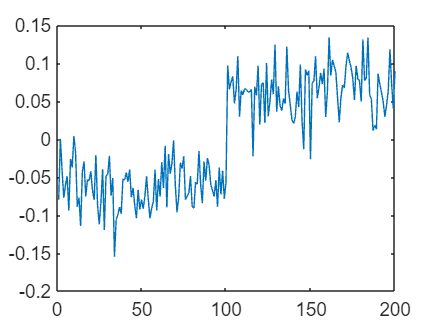


mu_1_mat = repmat(mu_1,  1, n/2); %each column is one observation
mu_2_mat = repmat(mu_2, 1, n/2);%each column is one observation
x_noiseless = [ mu_1_mat  mu_2_mat ];%each column is one observation 
x_noisy = x_noiseless +  mvnrnd(zeros(p,1), Sigma, n)';
H_hat = (x_noisy' * x_noisy)/n;
[V,D] = eig(H_hat);
[d,ind] = sort(diag(D), "descend");
Ds = D(ind,ind);
Vs = V(:,ind);
[cluster_est_now,C] = kmeans(Vs(:,1:2),K);
plot(Vs(:,1))

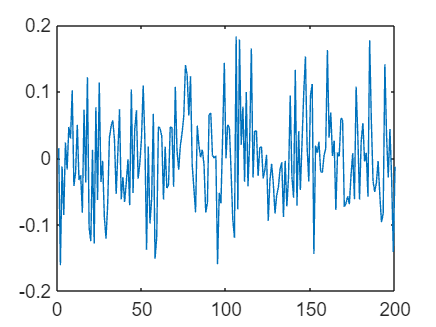

plot(Vs(:,2))

if true
    100
end

ans = 100